%%%% HW 1

## Problem 12c

Engs105. W24 - Prof. Paulsen

### Analytical Solution

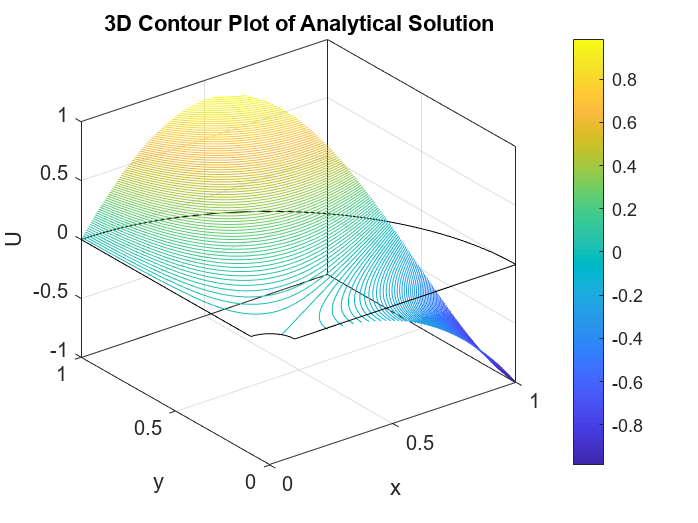

clear; close all;
% Parameters
a = 0.1;
R = 1;
th_final = pi/2;
b = a^6;

N = 100;

% Function for U(r, th)
U = @(r, th) - (r.^3 + b*r.^(-3)) / (1 + b) .* cos(3*th);

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);

r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);

x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);

U_mesh = U(r_mesh, th_mesh);

figure
contour3(x_coor, y_coor, U_mesh, 151)
hold on
plot3(zeros(N, 1), linspace(a, R, N), zeros(N, 1), 'k')
plot3(linspace(a, R, N), zeros(N, 1), zeros(N, 1), 'k')
plot3(a*cos(th_range), a*sin(th_range), zeros(N, 1), 'k')
plot3(R*cos(th_range), R*sin(th_range), zeros(N, 1), 'k')
title('3D Contour Plot of Analytical Solution')
xlabel('x')
ylabel('y')
zlabel('U')
colorbar

exportgraphics(gcf, 'ContourPlot.png', 'Resolution',300)

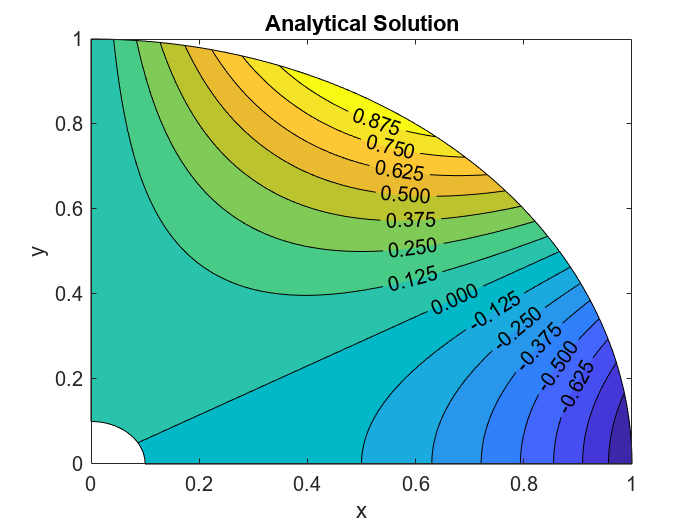


figure
contourf(x_coor, y_coor, U_mesh, 15, "ShowText","on", "LabelFormat","%0.3f",  "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Analytical Solution')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)

### Numerical Solution

#### N = 5

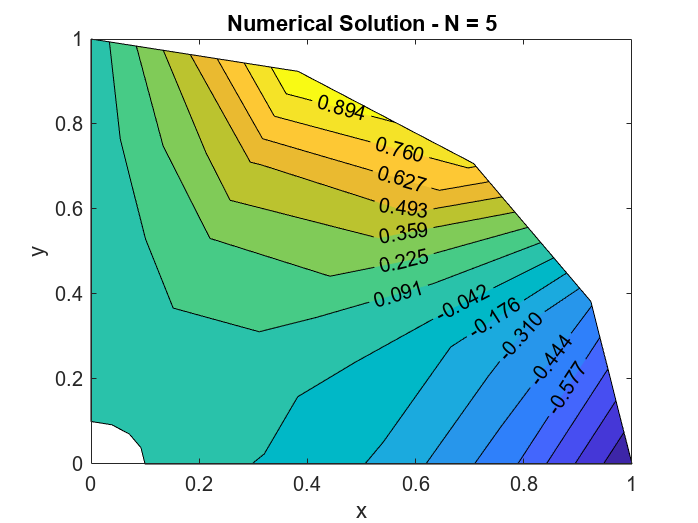

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% N = 5
N = 5;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("5.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 15, "ShowText","on", "LabelFormat","%0.3f",  "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - N = 5')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineN5.png', 'Resolution',300)

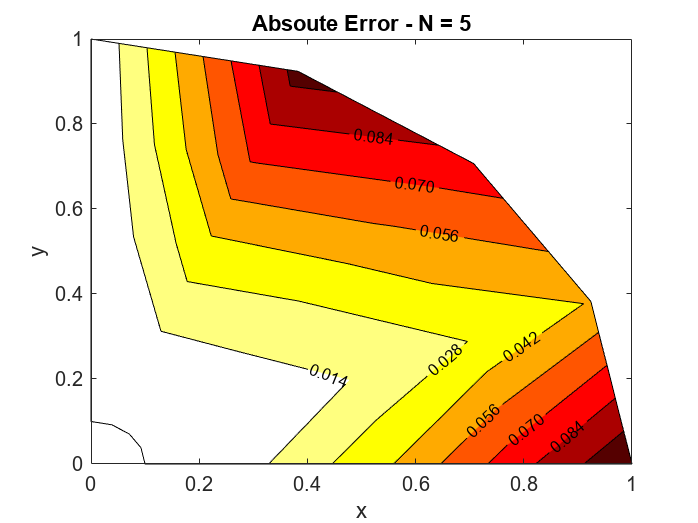


%%%% Error
error_mesh = abs(X_mesh - U(r_mesh, th_mesh));

%Setting colorbar limits
bottom = 0;
top  = max(max(error_mesh));

figure
[C, h] = contourf(x_coor, y_coor, error_mesh, 7, "LabelFormat","%0.3f",  "LabelSpacing",2000);
clabel(C, h, "FontSize", 8)
colormap(flipud(hot))
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Absoute Error - N = 5')
xlabel('x')
ylabel('y')
clim manual
clim([bottom top]);
exportgraphics(gcf, 'ErrorN5.png', 'Resolution',300)

#### N = 10

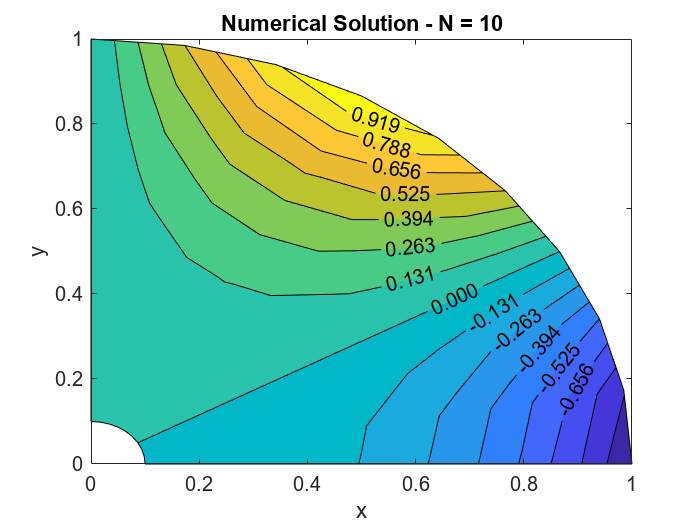

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% N = 10
N = 10;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("10.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 15, "ShowText","on", "LabelFormat","%0.3f",  "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - N = 10')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineN10.png', 'Resolution',300)

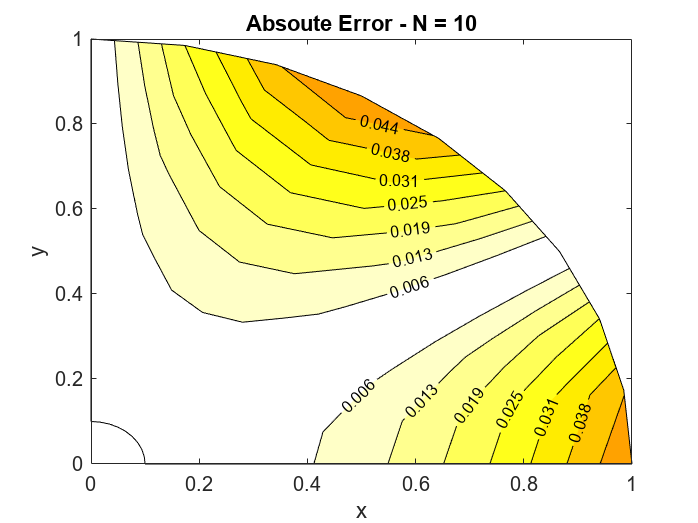


%%%% Error
error_mesh = abs(X_mesh - U(r_mesh, th_mesh));
figure
[C, h] = contourf(x_coor, y_coor, error_mesh, 7, "LabelFormat","%0.3f", "ShowText","on", "LabelSpacing",2000);
clabel(C, h, "FontSize", 8)
colormap(flipud(hot))
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Absoute Error - N = 10')
xlabel('x')
ylabel('y')
clim manual
clim([bottom top]);
secondPos = get(gca, 'Position');
exportgraphics(gcf, 'ErrorN10.png', 'Resolution',300)

#### N = 80

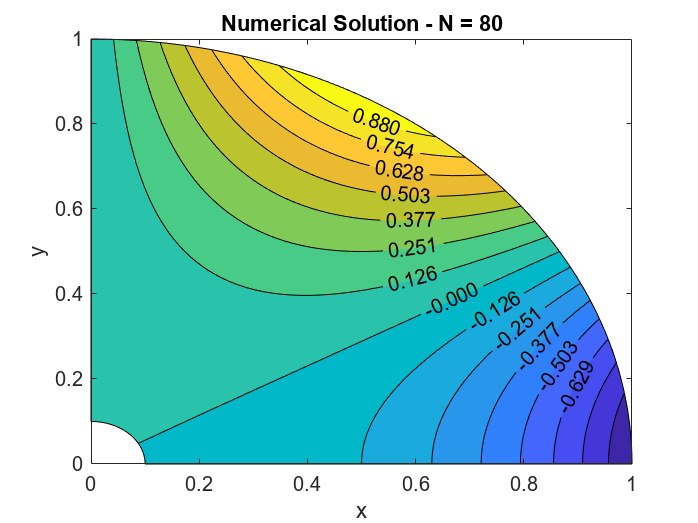

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% N = 80
N = 80;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("80.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 15, "ShowText","on", "LabelFormat","%0.3f", "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - N = 80')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineN80.png', 'Resolution',300)

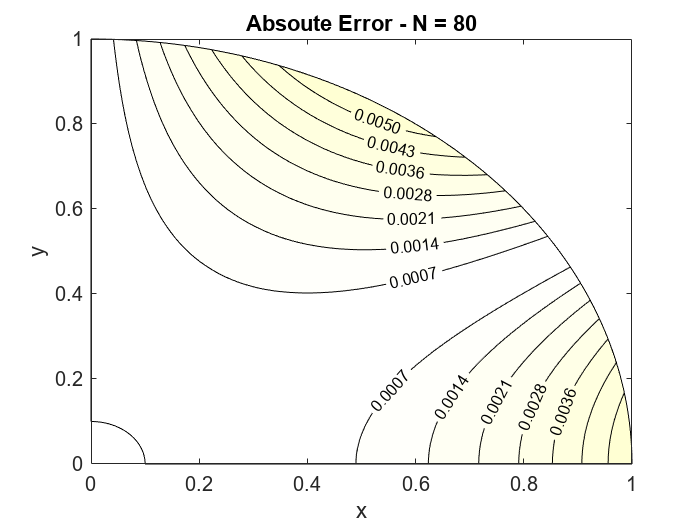


%%%% Error
error_mesh = abs(X_mesh - U(r_mesh, th_mesh));
figure
[C, h] = contourf(x_coor, y_coor, error_mesh, 7, "LabelFormat","%0.4f", "ShowText","on",  "LabelSpacing",2000);
clabel(C, h, "FontSize", 8)
colormap(flipud(hot))
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Absoute Error - N = 80')
xlabel('x')
ylabel('y')
clim manual
clim([bottom top]);
exportgraphics(gcf, 'ErrorN80.png', 'Resolution',300)

#### N = 200

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% N = 200
N = 200;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("200.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

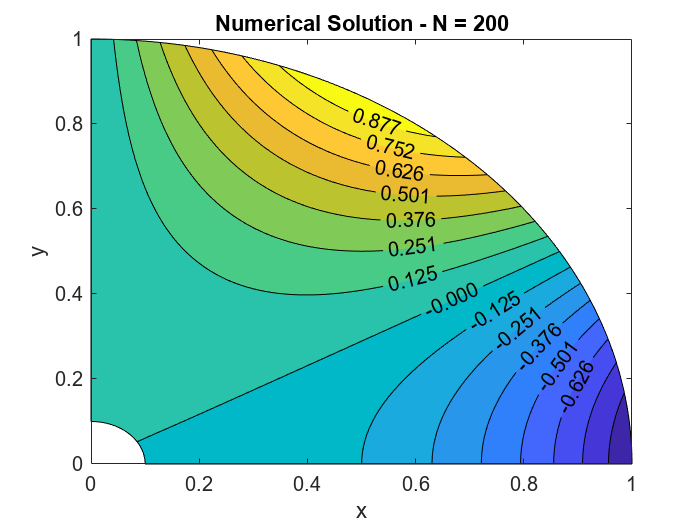


figure
contourf(x_coor, y_coor, X_mesh, 15, "ShowText","on", "LabelFormat","%0.3f",  "LabelSpacing",2000)
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - N = 200')
xlabel('x')
ylabel('y')
exportgraphics(gcf, 'IsolineN200.png', 'Resolution',300)

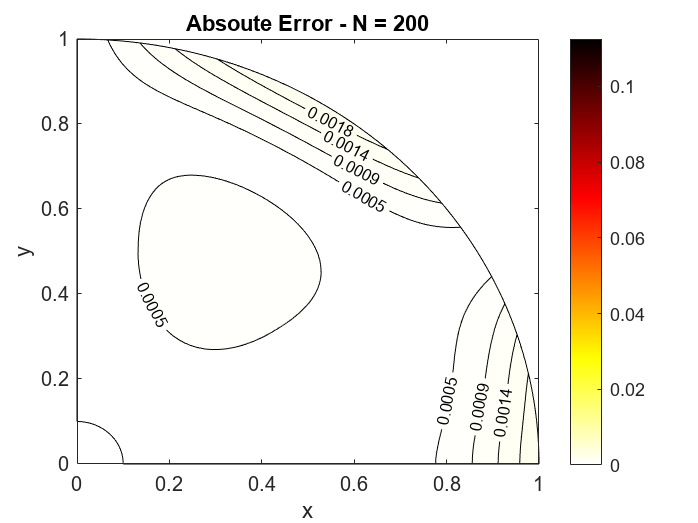


%%%% Error
error_mesh = abs(X_mesh - U(r_mesh, th_mesh));
figure
[C, h] = contourf(x_coor, y_coor, error_mesh, 4, "LabelFormat","%0.4f", "ShowText","on",  "LabelSpacing",2000);
clabel(C, h, "FontSize", 8)
colormap(flipud(hot))
colorbar
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Absoute Error - N = 200')
xlabel('x')
ylabel('y')
clim manual
clim([bottom top]);
exportgraphics(gcf, 'ErrorN200.png', 'Resolution',300)

### RMS Error v/s Delta R

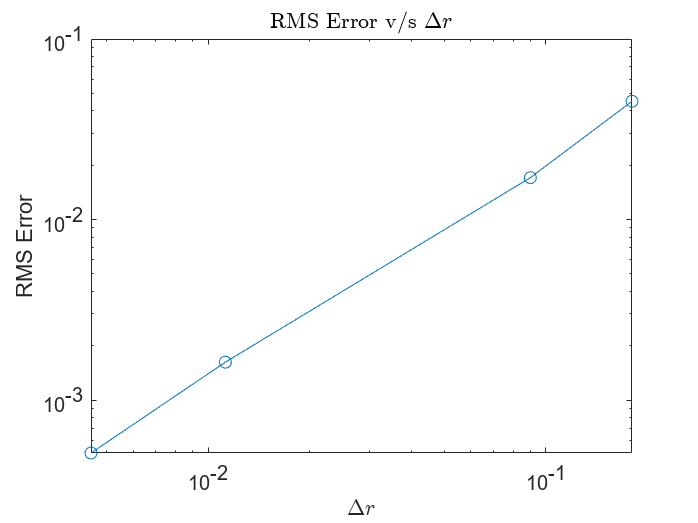

nrange = [5, 10, 80, 200];
rms_error = zeros([size(nrange), 1]);
for i = 1:length(nrange)
    % Ranges for independent variables
    r_range = linspace(a, R, nrange(i));
    th_range = linspace(0, th_final, nrange(i));
    r_mesh = repmat(r_range, nrange(i), 1);
    th_mesh = repmat(th_range', 1, nrange(i));

    filename = sprintf('%d.txt', nrange(i));
    ana_sol = U(r_mesh, th_mesh);
    data = readmatrix(filename);
    data_mesh = reshape(data, [nrange(i), nrange(i)]);
    data_mesh = -data_mesh';
    rms_error(i) = rms(data_mesh - ana_sol, 'all');
end
delrRange = (1-0.1) ./ nrange;
figure
loglog(delrRange, rms_error, 'o-')
xlabel('$\Delta r$', 'Interpreter', 'latex')
ylabel('RMS Error')
title('RMS Error v/s $\Delta r$', 'Interpreter', 'latex');
exportgraphics(gcf, 'RMSerror.png', 'Resolution',300)

p = polyfit(log(delrRange), log(rms_error), 1)

p =     1.1953   -1.1063
